# **System 6 : Ausbereitungsmodell einer Infektionskrankheit**

Eine Infektionskrankheit kann durch folgende Modell beschrieben weiden:

    
$$\frac{\mathrm{d}y(t)}{\mathrm{d}t}= k*y(t)*[1-y(t)]$$


mit k = 0.10   y(t=0) = 0.01     und eine Dauer von 100 Zeiteinheit

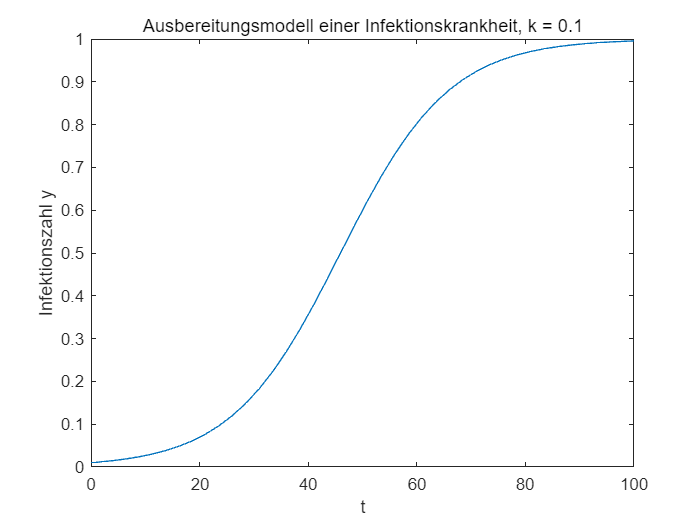


k = 0.1;
ode = @(t,y) [k*y*(1-y)];
tSpan = [0 100];
y0 = 0.01;

[t,y,k] = ode45(ode,tSpan,y0);

plot(t,y(:,1))
xlabel('t')
ylabel('Infektionszahl y')
title('Ausbereitungsmodell einer Infektionskrankheit, k = 0.1')